# Proyecto de ciencia de los datos

## Universidad Autónoma del Estado de México

## CU UAEM Zumpango

## Ingeniería en Computación

## Ciencia de los Datos

## Integrantes:

## Kevin Omar Lazaro Ortega

## Fernando Emmanuel Santacruz Lara

## Isaac Antonio Maldonado 

## Profesor: Asdrúbal López Chau

## Noviembre 2022

## Conjunto de datos

Los datos analizados en está ocasión son precios historicos de las acciones de varias empresas que se desarrollan en el ambito tecnologico, las cuales son Amazon, Apple, Intel, NVidia, Google, Uber, Facebook, Netflix y Tesla. Estos conjuntos de datos consisten en describir los precios de las acciones de las empresas, empezando algunas en los año 1980 hasta Marzo de 2022. Los campos considerados dentro de los datos son Date(Fecha), Open(Precio de apertura), Close(Precio de cierre), Adj Close(Precio de cierre ajustado), High(Precio más alto), Low(Precio más bajo) y Volume(Promedio de ventas de la acción).

ds = datastore("../Datasets","ReadVariableNames",true,"VariableNamingRule","preserve");
[data,labels,atributos] = generateData(ds);
data

data = 70841×7 table
    empresas      Volume      Open      Low     High        Date       Close
    ________    __________    _____    _____    _____    __________    _____

     "AAL"       9.612e+05    21.05     19.1     21.4    2005-09-27     19.3
     "AAL"      5.7479e+06     19.3     19.2    20.53    2005-09-28     20.5
     "AAL"      1.0782e+06     20.4     20.1    20.58    2005-09-29    20.21
     "AAL"      3.1233e+06    20.26    20.18    21.05    2005-09-30    21.01
     "AAL"      1.0579e+06     20.9     20.9    21.75    2005-10-03     21.5
     "AAL"      1.7688e+06    21.44    21.44     22.5    2005-10-04    22.16
     "AAL"       9.043e+05     22.1    21.75    22.31    2005-10-05     22.2
     "AAL"      1.6142e+06     22.6     22.4   

## Preguntas 

¿Conviene invertir en acciones después de la pandemia?

Los estragos de la pandemia se viven actualmente en cualquier ambito, por lo que preguntarse si vale la pena invertir en alguna de las empresas mencionadas es algo a lo que se busca dar una solución o un acercamiento a la respuesta, por lo que se plantea la pregunta anterior. Se busca dar solución con regresión lineal, con la cual podemos formular la hipotesis de si "El volumen de ventas de acciones, depende de el precio de cierre ajustado, a lo largo de los 3 años analizado"

¿Cómo afecto la Pandemia anualmente a la venta de acciones?

Saber que paso con las acciones de las empresas ante una crisis como lo fue la pandemia, es algo que nos resulya util para responder la pregunta anterior y así saber cual fue la reacción del mercado financiero ante un reto nunca antes visto. Daremos solución con la grafica de los promedios por año de cada una de las empresas

¿En que año de la pandemia la venta acciones tuvieron comportamiento brusco?

El ambito financiero es un subir y bajar, las compañias enfocadas en la tecnología, poco a poco dominan el mercado, por lo que se requiere saber en que año se tuvo una repercusión positiva o negativa, la cual resalte a comparación de los demas. Usando de igual manera los promedios y sus grafos se busca interpretar en que año de pandemia se percibe alguna anormalidad

¿Qué relación se tuvo en cuanto a los precios de apertura y cierre en la pandemia?

La pregunta es util para determinar futuros comportamientos en la venta de acciones, en está ocasión, saber si existe alguna relación entre el precio ajustado de cierre y el volumen de ventas. Esta pregunta la respondemos con el coeficiente de pearson que busca tener una relación entre el aumento de los precios de cierre y apertura, los cuales son importantes para determinar el volumen de ventas

¿Cual fue el peor año de pandemia para la venta de acciones?

Saber cual fue el año con mayor caida, de esa manera se espera conocer si el mercado financiero cambio al inicio o final del rango de años que se tiene. Dando solución a esta pregunta hacemos uso del promedio de volumenes, tanto en su forma grafica como numerica.

## Análisis Exploratorio

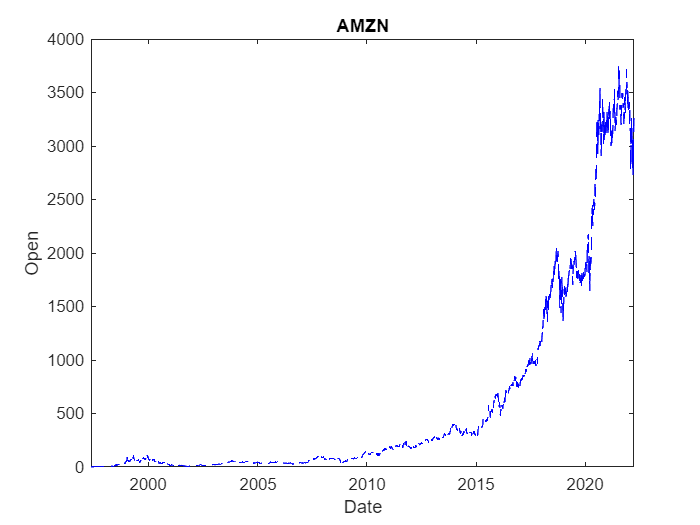

ans = 2×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 


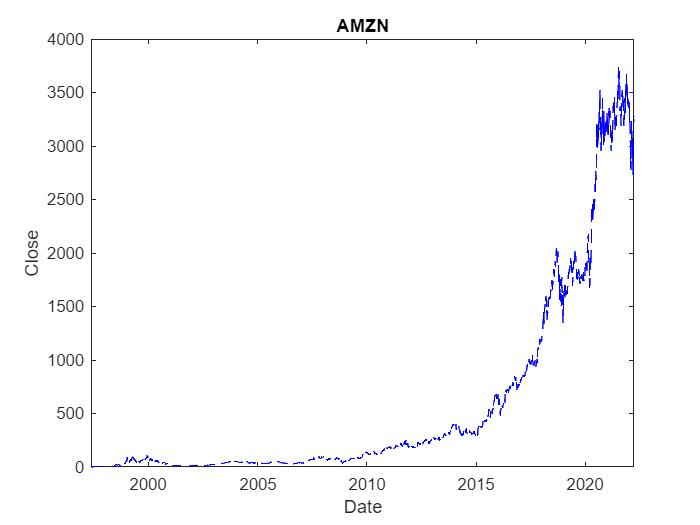

ans = 2×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 


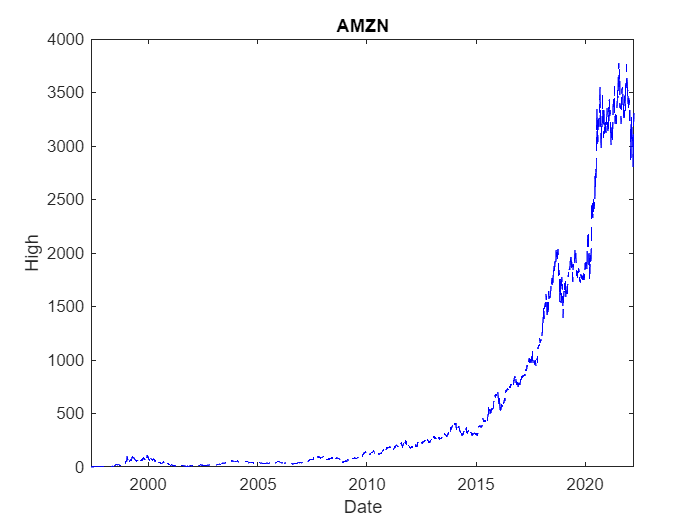

ans = 2×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 


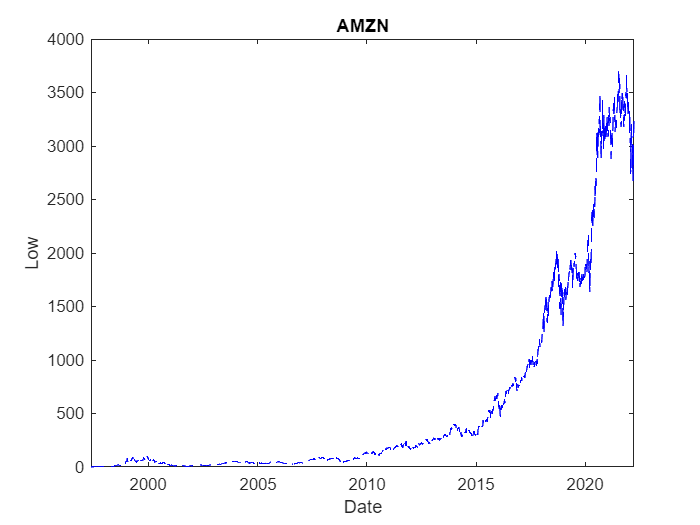

ans = 2×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 


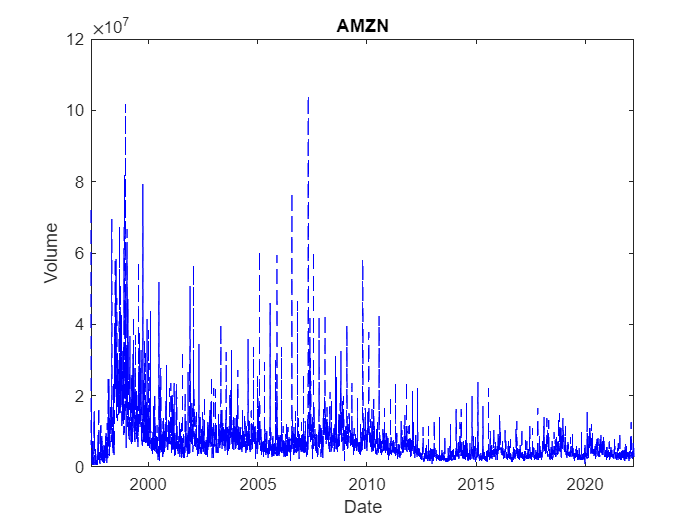

ans = 2×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 


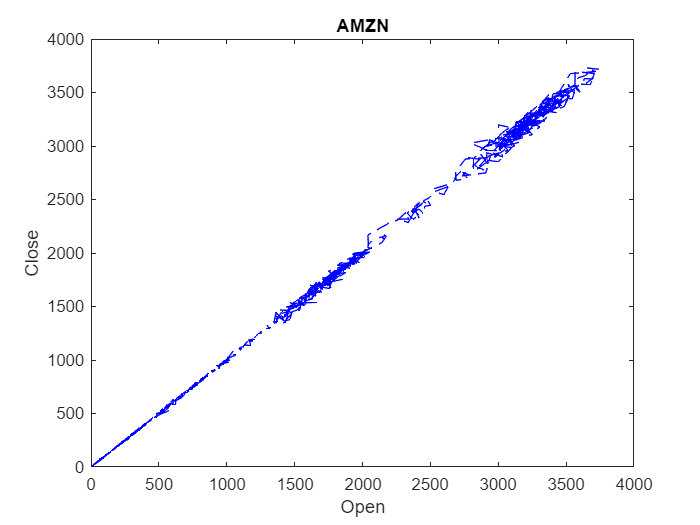

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


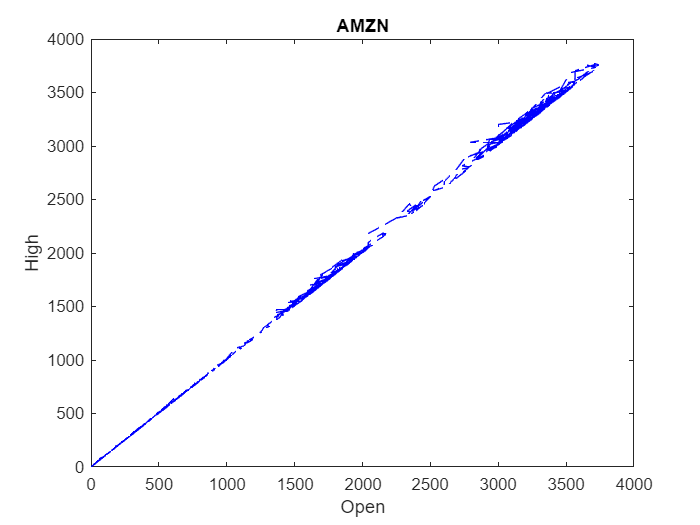

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


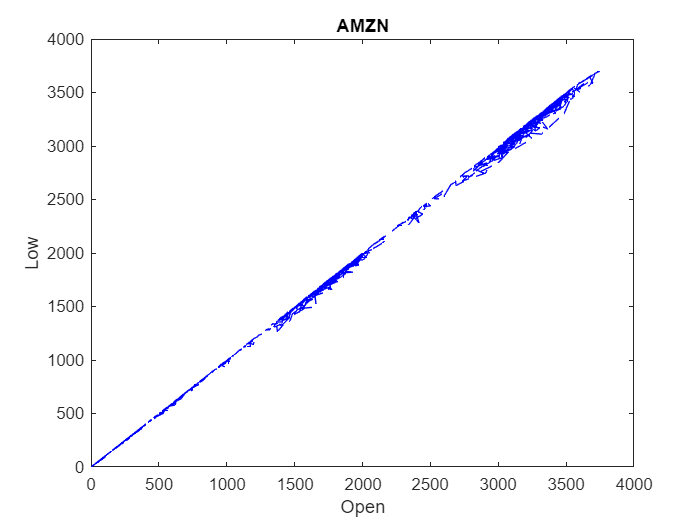

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


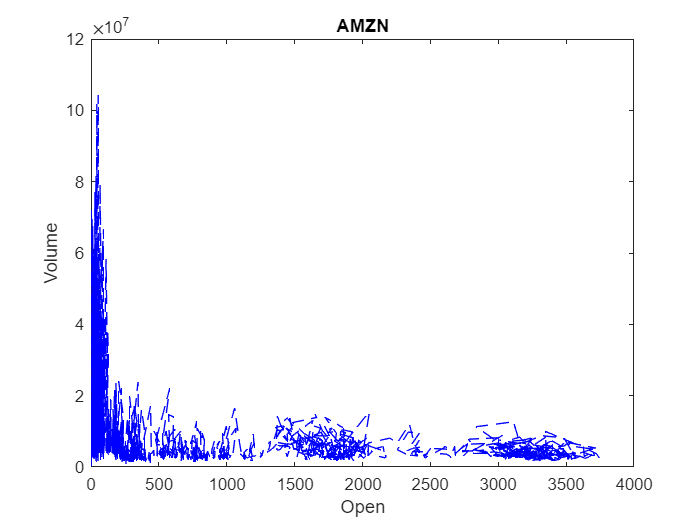

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


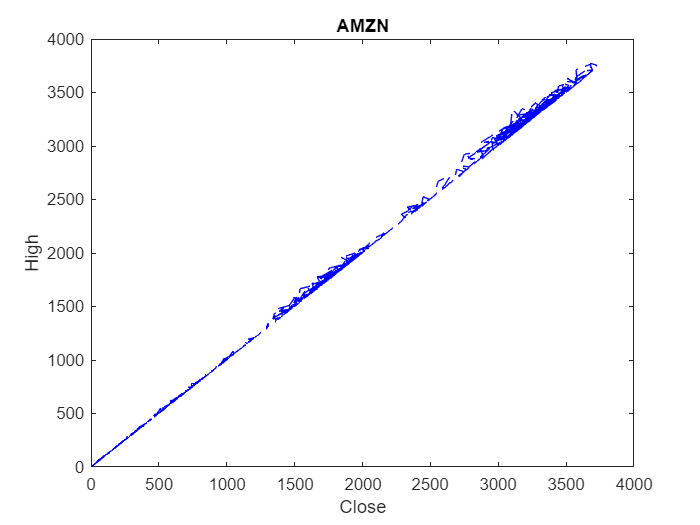

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


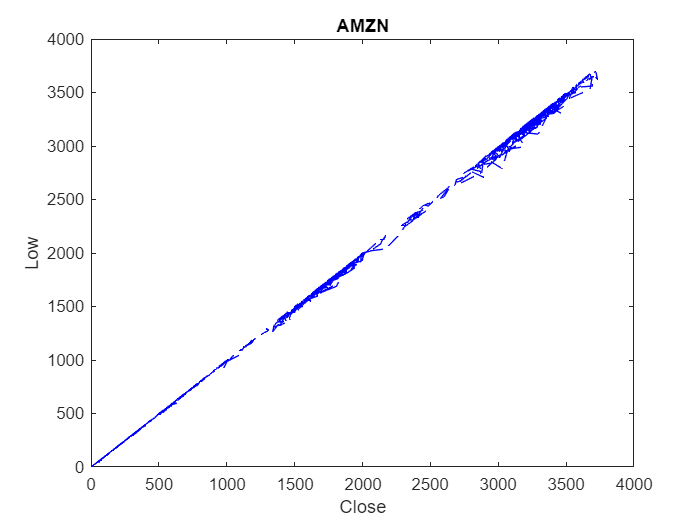

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


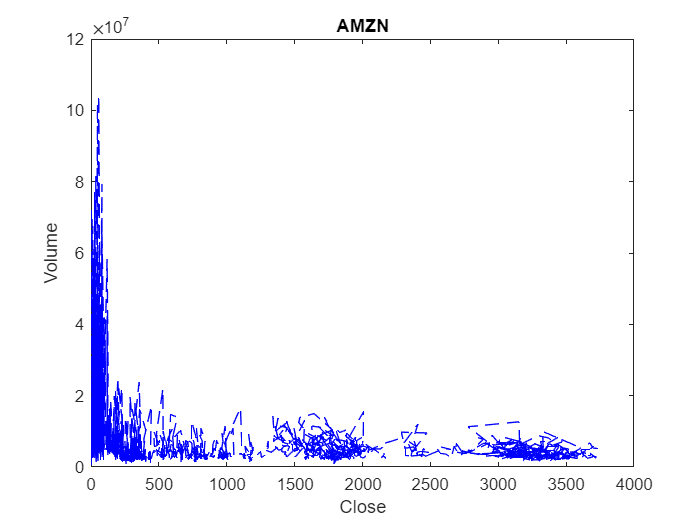

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


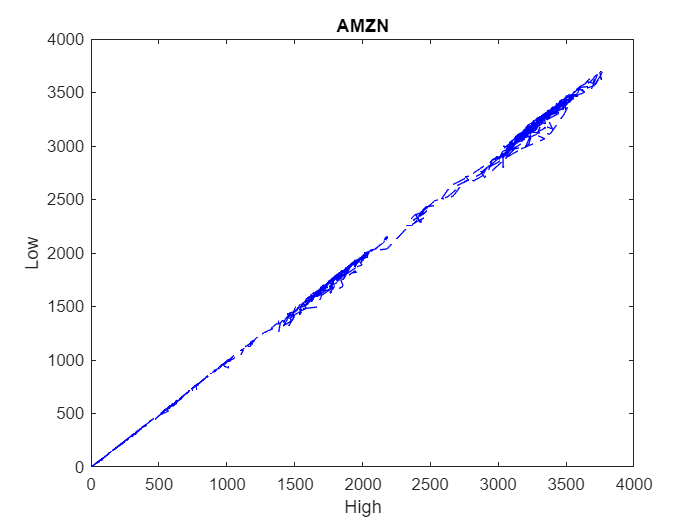

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


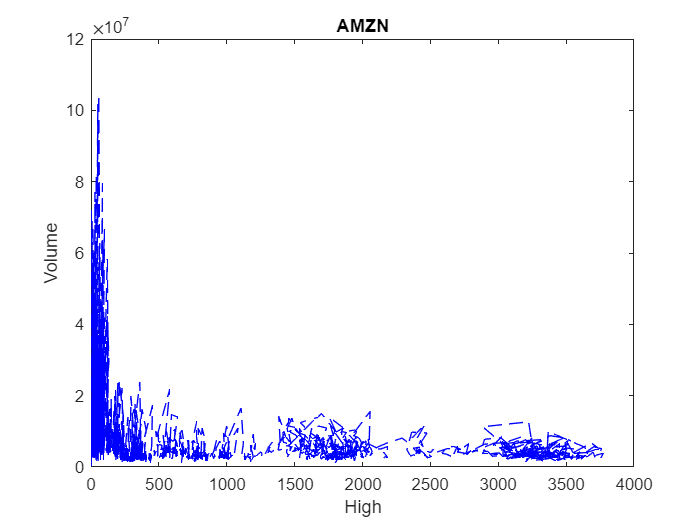

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


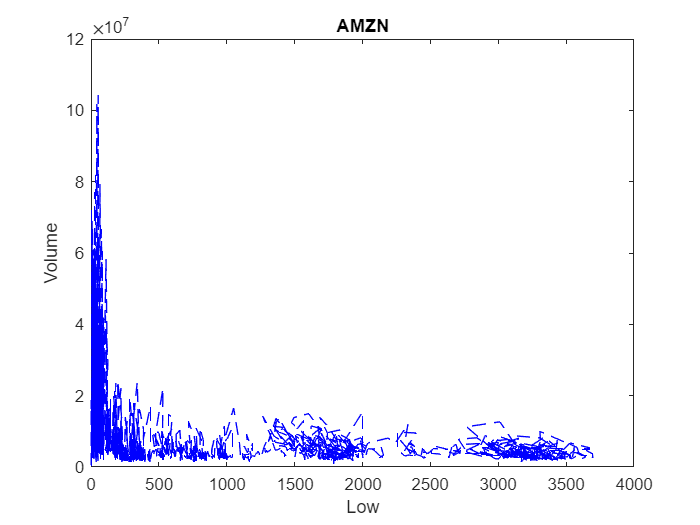

ans = 4×1 table
    estadisticas
    ____________

     1×8 string 
     1×8 string 
     1×8 string 
     1×8 string 


compania = "AMZN";
indices = find(data.empresas == compania);
datos=(data(indices(1):indices(end),:));
statics(datos,atributos); 

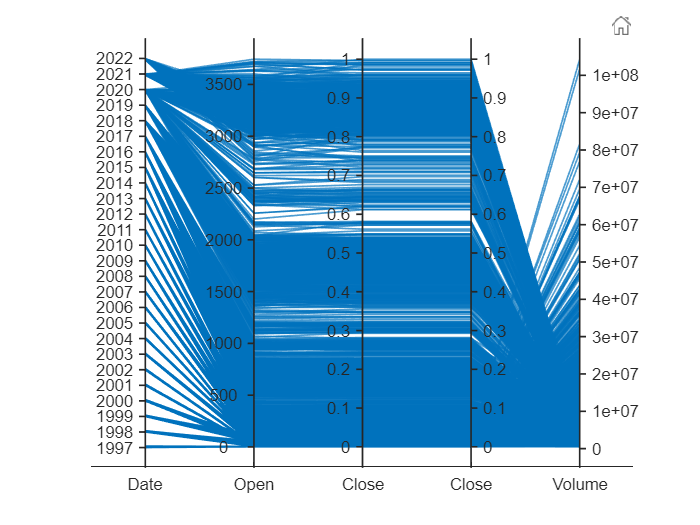

datos.Date = categorical(datos.Date.Year);
grafica = parallelplot(datos);
grafica.CoordinateVariables = {'Date','Open','Close','Close','Volume'};

## Análisis de los datos

Aplicar los métodos necesarios.

Limpieza de los datos.

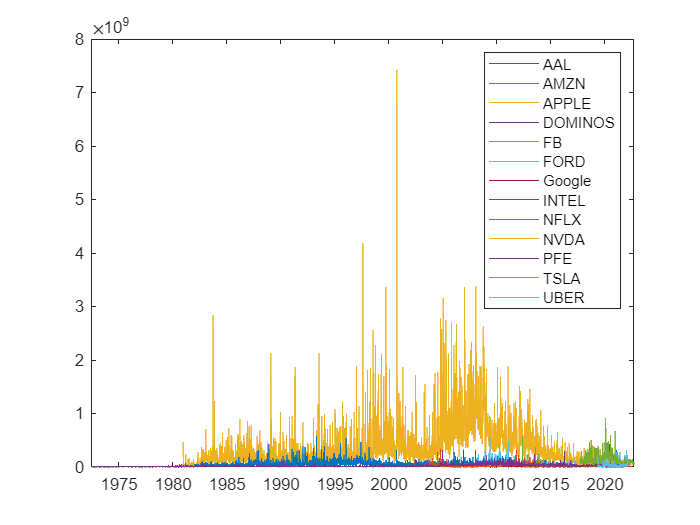

empresas = unique(data.empresas);
[tam,~] = size(empresas);
years = ["2019","2020", "2021", "2022"];
for i=1:tam
    indices = find(data.empresas == empresas(i,1));
    datos = data(indices(1):indices(end),:);
    plot(datos.Date,datos.Volume);
    hold on
end
legend(empresas);
ylim tickaligned
hold off

compania = "AAL";
indices = find(data.empresas == compania);
datos=(data(indices(1):indices(end),2:end));
[numHiddenUnits,numFeatures] = size(datos);
numResponses = 6;
layers = [sequenceInputLayer(numFeatures), lstmLayer(numHiddenUnits,'OutputMode','sequence'), fullyConnectedLayer(numResponses),regressionLayer];
[XTrain,YTrain] = chooseSets(datos,0.80);
maxEpochs = 60;
options = trainingOptions('adam', ...
        'ExecutionEnvironment','cpu',...
        'MaxEpochs',maxEpochs, ......
        'InitialLearnRate',0.01, ...
        'GradientThreshold',1, ...
        'Shuffle','never', ...
        'Plots','training-progress',...
        'Verbose',0);
net = trainNetwork(table(XTrain.Date),YTrain.Open,layerGraph(layers),options)

Error using trainNetwork
Too many input arguments.

Caused by:
    Error using nnet.internal.cnn.trainNetwork.DLTInputParser>iParseInputArguments
    Too many input arguments.

## Hallazgos

Al aplicar los distintos analisis a los datos se encontraron hallazgos, esperados y otros de los cuales no se buscaba una respuesta. Los hallazgos que se obtuvieron al realizar nuetro proceso fue en primer lugar una fuerte crisis de compras compulsivas de acciones, las cuales se ven reflejadas en el grafo de promedios anuales del volumen de ventas, donde en su mayoría de veces se nota un discreto o gran aumento del volumen de ventas que comprende el perido de 2019 - 2022, por lo que se interpreta como una crisis de compras compulsivas. El siguiente hallazgo es encontrado en el mismo grafo, el cual nos indica que del año 2019 - 2020 se tienen los cambios más significativos a la alza, y a la baja va del año 2020 - 2021, esto se puede interpretar como una consecuencia del fenomeno de compras compulsivas. Otro hallazgo dentro del mismo grafo es que con apenas el 22% de avance del año 2022, el volumen de ventas va a la alza, por lo que se puede interpretar que algo positivo depara el periodo 2022 - 2023.

El siguiente hallazgo se encuentra en el coeficiente de Pearson , al tener un valor cercano a 1, podemos determinar que a medida de que un valor de cierre aumenta, el de apertura aumentara, en pocas palabras existe una gran relación entre ellos. En terminos financieros podriamos interpretar este resultado como los dos elementos que más se consideran para comprar una acción.

Por ultimo podemos determinar un hallazgo, la fuerte relación que se tiene entre el precio de cierre ajustado y el volumen de ventas a lo largo de los años de pandemia, donde al tener en p un valor menor a 0.05, podemos determinar que el valor del predictor(Volume) se relaciona con la cambios en la variable de respuesta(adj close).

## Conclusiones

Para dar conclusión al proyecto realizado, se establecen los indicadores de exito, respecto a las expectativas iniciales. Donde se puede concluir que las preguntas fueron contestadas en su mayoria de forma clara y si no fue así se dio un fuerte acercamiento a lo que sería una interpretación de expertos en el ambito financiero. Para concluir este trabajo daremos respuesta a la pregunta principal "¿Conviene invertir en acciones después de la pandemia?"; las empresas presentadas en este trabajo son enfocadas a la tecnología y podemos ver un incremento en la venta de acciones, así cómo su valor, por lo que podemos concluir que invertir en acciones después de la pandemía es seguro y conviene, siempre y cuando sea en una empresa dedicada a la tecnología, ya que la tecnología está teniendo un gran crecimiento y hay que aprovechar dicho crecimiento.

## Funciones de Ayuda

function empresas = generateLabels(label,size)
    empresas = [];
    for i = 1:size
        empresas = [empresas ;label];
    end
    empresas = table(empresas);
end
function [data,labels,atributos] = generateData(ds)
names = ds.Files;
atributos = [];
[numFiles,~] = size(names);
files = [];
variables = [];
Tables = [];
for i = 1:numFiles
    nombre = string(names(i));
    table = readtable(nombre,"VariableNamingRule","preserve");
    variables = [variables table.Properties.VariableNames];
end
headers =  unique(variables);
[row,column] = size(headers);
uniqueHeaders = [];
for i = 1:column
    indices= find (variables== string(headers(i)));
    [~,occurrence] = size(indices);
    if occurrence == numFiles
        uniqueHeaders = [uniqueHeaders string(headers(i))];
    end
end
atributos = ["Date" "Open" "Close" "High" "Low" "Volume"];
data = [];
labels = [];
for i = 1:numFiles
    tab = [];
    nombre = string(names(i));
    lastCSV = strfind(nombre,".csv");
    label = extractBetween(nombre,100,lastCSV-1);
    table = readtable(nombre,"VariableNamingRule","preserve");
    cabeceras = table.Properties.VariableNames;
    [~,num] = size(uniqueHeaders);
    for j = 1:num
        coin = find(cabeceras == uniqueHeaders(j));
        tab = [table(:,coin) tab];
    end
    [rows,~] = size(tab);
    label = generateLabels(label,rows);
    tab = [label tab];
    labels = [labels; label];
    data = [data;tab];
    end
end
function plots = statics(datos,atributos)
    [~,n]=size(datos.Properties.VariableNames);
    for i = 2:n-1
        a = table2array(datos(:,datos.Properties.VariableNames == atributos(1,i-1)));
        for j=i:n-1
           figure
           b = table2array(datos(:,datos.Properties.VariableNames == atributos(1,j))); 
           plot(a,b,"b--")
           title(unique(datos.empresas));
           xlabel(atributos(i-1));
           ylabel(atributos(j));
           if(atributos(1,i-1) == "Date")
               estadisticas = ["" "media" "mediana" "moda" "Desviacion Estandar" "Varianza" "Covarianza" "Correlacion";atributos(j) mean(b) median(b) mode(b) std(b) var(b) cov(b) corrcoef(b)];   
           else
              estadisticas = ["" "media" "mediana" "moda" "Desviacion Estandar" "Varianza" "Covarianza" "Correlacion" ;atributos(i-1) mean(a) median(a) mode(a) std(a) var(a) cov(a) corrcoef(a) ;atributos(j) mean(b) median(b) mode(b) std(b) var(b) cov(b) corrcoef(b)];
              estadisticas = [estadisticas;
              "Correlacion de Pearson" "" "" "" "" corr(a,b,'type','Pearson') "" "" ];
              
           end
           table(estadisticas)
        end
    end
end
function [x,y] = chooseSets(datos,percent)
    [cant,~] = size(datos);
    indices = [];
    test = size(indices);
    value = cant*percent;
    while test < value;
        random = randi(cant,1,1);
        if isin(indices,random) ~= 1
            indices = [indices;random];
            [test,~] = size(indices);
        end
    end
    indices = sort(indices);
    x = [];
    y = [];
    for i = 1:value-1
        x = [x; datos(indices(i),:)];
        y = [y; datos(indices(i)+1,:)];
    end
    
end
function logic = isin(arr,var)
    [cant2,~] = size(arr);
    logic = 0;
    for i=1:cant2
        if arr(i) == var
            logic = 1;
        end
    end
end